## Tarea 01: Ajuste por mínimos cuadrados

Juan Diego Murcia Porras - jmurciap@unal.edu.co

Brayan Alejandro Romero Castro - brromeroc@unal.edu.co

Carlos Enrique Nosa Guzman - cnosa@unal.edu.co

### Ejercicio 2

La misma idea del ajuste polinomial se puede aplicar para el ajuste de otro tipo de funciones $f$. Estas también satisfacen que:

$\sum_{i=1}^{m}|y_i - f(x_i)|^2$ sea mínima.

En las aguas de un lago hay tres clases de microorganismos provocadores de enfermedades. Se sabe que, en respuesta a un tratamiento aplicado a las aguas, los microorganimos están disminuyendo en forma exponencial de acuerdo al modelo:


$$p(t) = c_1 e^{-1.5 t}+ c_2 e^{-0.3t}+c_3 e^{-0.05t}, \quad t\geq 0,$$


donde $p(t)
$ da el número (en miles) de microorganismos. De una muestra de las aguas, en un laboratorio se obtuvieron los datos que se muestran en la tabla a continuación:

Tabla: Número de microorganismos de la muestra (en miles).

a) Escriba el sistema de ecuaciones lineales asociado al problema de encontrar la función exponencial $p(t)
$ que mejor ajusta por cuadrados mínimos los datos en la tabla.

b) Escriba un rutero en Matlab que haga lo siguiente:

- Construya la matriz $A$ y parte derecha y del sistema escrito por usted en la parte a).

- Resuelva el sistema $\textrm{Ay}=c$ en el sentido de los mínimos cuadrados.

- Grafique en un mismo gráfico los pares en la tabla y la función $p\left(t\right)$ obtenida.

- En base a la función obtenida, ¿cuál es el número de microorganismos que había en la muestra inicialmente? ¿y después de una hora y media? ¿y después de 5 horas y media?

***Solución***

***a)*** Utilizando los datos de la tabla vemos que queremos ajustar $c_1$, $c_2$, $c_3$ de tal foma que se tenga:


$$\left \{ \begin{array}{rcl} 
c_1 e^{-1.5(0.5)}+c_2 e^{-0.3(0.5)}+c_3e^{-0.05(0.5)} &=&7\\
c_1 e^{-1.5}+c_2e^{-0.3}+c_3e^{-0.05} &=& 5.2\\
c_1 e^{-1.5(2)}+c_2e^{-0.3(2)}+c_3e^{-0.05(2)} &=& 3.8 \\
c_1 e^{-1.5(3)}+c_2e^{-0.3(3)}+c_3e^{-0.05(3)} &=&3.2 \\
c_1 e^{-1.5(4)}+c_2e^{-0.3(4)}+c_3 e^{-0.05(4)}&=&2.5\\

\end{array}  \right.$$


***b)*** 

- Lo anterior puede ser desrito de forma matricial como:

$\left\lbrack \begin{array}{ccc}
e^{-1\ldotp 5\left(0\ldotp 5\right)}  & e^{-0\ldotp 3\left(0\ldotp 5\right)}  & e^{-0\ldotp 05\left(0\ldotp 5\right)} \\
e^{-1\ldotp 5}  & e^{-0\ldotp 3}  & e^{-0\ldotp 05} \\
e^{-1\ldotp 5\left(2\right)}  & e^{-0\ldotp 3\left(2\right)}  & e^{-0\ldotp 05\left(2\right)} \\
e^{-1\ldotp 5\left(3\right)}  & e^{-0\ldotp 3\left(3\right)}  & e^{-0\ldotp 05\left(3\right)} \\
e^{-1\ldotp 5\left(4\right)}  & e^{-0\ldotp 3\left(4\right)}  & e^{-0\ldotp 05\left(4\right)} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
7\\
5\ldotp 2\\
3\ldotp 8\\
3\ldotp 2\\
2\ldotp 5
\end{array}\right\rbrack$

- Utilizando  el comando  de matlab "\" podemos solucionar el anterior sistema, como se muestra en el siguiente codigo:

I2 = [0.5 1 2 3 4 ;7 5.2 3.8 3.2 2.5]; %Datos proporcionados
%Matriz y vector asociadas
A2 = transpose([exp(-1.5*I2(1,:)); exp(-0.3*I2(1,:)); exp(-0.05*I2(1,:))]);
y2 = transpose(I2(2,:));

% Sistema por mínimos cuadrados
c2 = A2\y2;

          Con el anterior código podemos ver que  la solución a nuestro sistema es:

$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
4\ldotp 9745\\
3\ldotp 0079\\
2\ldotp 0683
\end{array}\right\rbrack$

- Utilizando el comando plot, podemos Gráficar los datos anteriores, quedandonos:

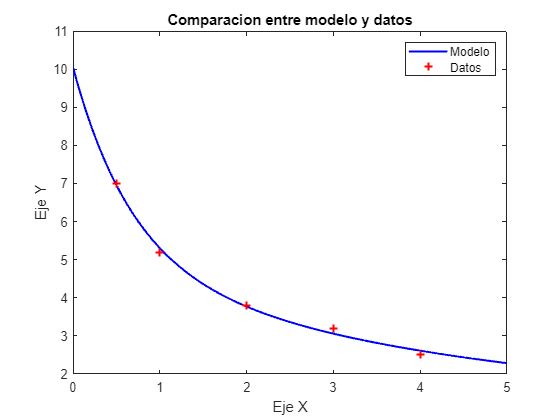

%Gráfica
X2 = 0:0.01:max(I2(1,:)+1); Y2= c2(1)*exp(-1.5*X2) + c2(2)*exp(-0.3*X2) + c2(3)*exp(-0.05*X2);
plot(X2,Y2,"b-",I2(1,:),I2(2,:),"r+",'LineWidth',1.5)
box on
xlabel('Eje X')
ylabel('Eje Y')
title('Comparacion entre modelo y datos')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')

- Los pronosticos son los siguientes según el código adjunto a este archivo:

 Microorganismos inicicales: 10.0508

Microorganismos en 1 hora y media: 4.3611

Microorganismos  en 5 horas y media: 2.1500

### Ejercicio 4

Para estimar la cantidad de vitamina A requerida para mantener el peso se dió a ratas de laboratorio una dieta básica exenta de vitamina A y se les administró raciones controladas de vitamina A en forma de tabletas. La tabla muestra la relación entre la cantidad de vitamina A administrada y el aumento de peso de las ratas.

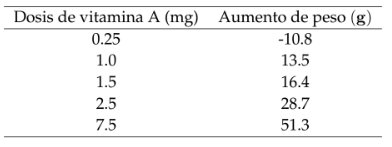

Tabla: Aumento de peso de las ratas al administrar vitamina A.

- Escriba un rutero MATLAB que,

Aumento de peso = $a+b\;\log_{10}$(Dosis de vitamina A), $a, b \in \mathbb{R}$

             que mejor ajusta por cuadrados mínimos los datos dados

- Grafique en un mismo gráfico los pares en la tabla y la función obtenida.

- Basado en la función obtenida, ¿qué cantidad de vitamina A es requerida para no aumentar de peso?

***Solución***

- Notemos que el sistema que tenemos que resolver (en forma matricial), por minimos cuadrados es el siguiente:


$$\left\lbrack \begin{array}{cc}
1 & \log_{10} \left(0\ldotp 25\right)\\
1 & \log_{10} \left(1\ldotp 0\right)\\
1 & \log_{10} \left(1\ldotp 5\right)\\
1 & \log_{10} \left(2\ldotp 5\right)\\
1 & \log_{10} \left(7\ldotp 5\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-10\ldotp 8\\
13\ldotp 5\\
16\ldotp 4\\
28\ldotp 7\\
51\ldotp 3
\end{array}\right\rbrack$$


Escrito como un rutero sería:


I4 = [0.25 1 1.5 2.5 7.5; -10.8 13.5 16.4 28.7 51.3]; %Datos proporcionados
%Matriz y vector asociadas
A4 = transpose([ones(1,5);log10(I4(1,:))]);
y4 = transpose(I4(2,:));

- Solucionarmos este sistema utilizando mldivide, que halla la solución por minimos cuadrados

c4 = mldivide(A4'*A4,A4'*y4);

Dandonos la solución:


$$\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
12\ldotp 7623\\
41\ldotp 6611
\end{array}\right\rbrack$$


- Utilizando el comando plot, podemos Gráficar los datos anteriores, quedandonos:

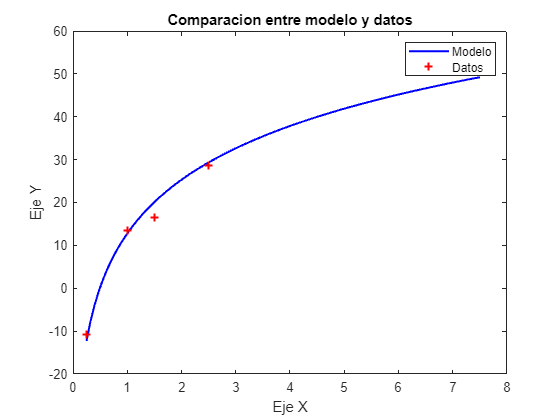

%Gráfica
X4 = 0.25:7.25/100:7.5; Y4= c4(1) + c4(2)*log10(X4);
plot(X4,Y4,"b-",I4(1,:),I4(2,:),"r+",'LineWidth',1.5)
box on
xlabel('Eje X')
ylabel('Eje Y')
title('Comparacion entre modelo y datos')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')

### Ejercicio 6: La genialidad de Leonardo Da Vinci

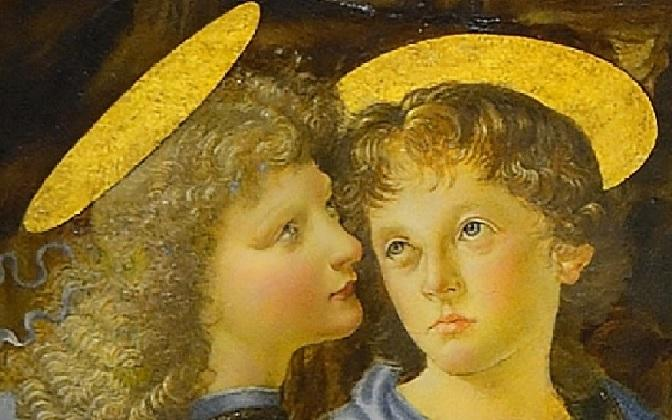

Figura 1. Fragmento de la pintura *Bautismo de Cristo.*

El objetivo en este ejercicio es conocer si el pupilo superó al maestro. En las pinturas medievales, las personas santas se distinguían con una aureola circular detrás de la cabeza. Durante el Renacimiento, el progreso de la ciencia transformó estas aureolas en elipses. Esto nos da la ocasión para presentar la precisión de una de las pinturas de Leonardo bajo investigación científica. Elegimos la pintura El Bautismo de Cristo de 1472, donde el joven alumno Leonardo añadió un ángel adicional (ángel a la izquierda) a una pintura de su maestro Andrea del Verrocchio (ver la Figura).

***Solución***

Con el fin de obtener datos de la aureola izquierda, se seleccionaron manualmente 22 puntos del borde de la figura geométrica con ayuda del código mostrado a continuación.

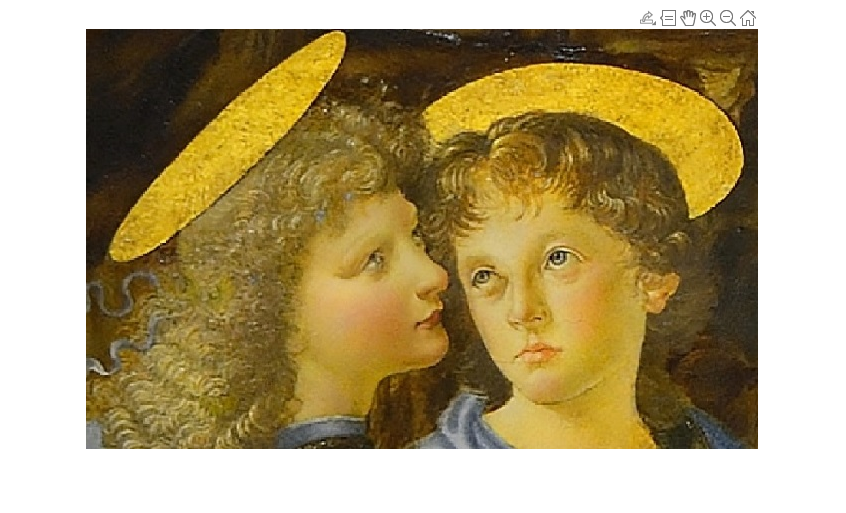

imshow('angeles.jpg')
[x1,y1] = ginput(22);

Luego de esto, se propone el modelo

$Ax^2+By^2+Cxy+Dx+Ey=10000$,

con parámetros desconocidos $A,B,C,D$ y $E$. La elección de este modelo se hace con el objetivo de expresar una cónica de manera general, en donde el término $\textrm{xy}$ tiene el fin de capturar la inclinación del objeto respecto a los ejes cartesianos y el término independiente $10000$ se escoge para 'regular' los datos de tal forma que los parámetros sean números en un rango 'cómodo' para graficar (Nota: La elección de la constante $10000$ se realizó dado que los datos tomados son de orden $10^{2}$ y en la matriz se convierten en datos de orden de $10^4 = 10000$. Esto ayuda a que los parámetros calculados por el método de los mínimos cuadrados estén en un rango en el que no se pierdan muchas cifras significativas).

Considerando el modelo planteado, se construye la matriz,

Eleft = [x1.*x1 y1.*y1 x1.*y1 x1 y1];

y se procede a la solución del sistema $E_{left}\cdot c = \mathbf{10000}$, en donde $\mathbf{10000}$ representa el vector columna de tamaño $22\times 1$con todas sus entradas iguales a $10000$,

cleft = mldivide(Eleft'*Eleft,10000*Eleft'*ones(22,1));

Al realizar es proceso obtenemos que

fprintf('%g ',cleft)

-0.158007 -0.157244 -0.295767 80.2103 78.7902 

en donde $c_{left}=(A,B,C,D,E)^{T}$.

Si graficamos los datos obtenidos versus la gráfica de la elipse hallada por el método de los mínimos cuadrados obtenemos lo siguiente,

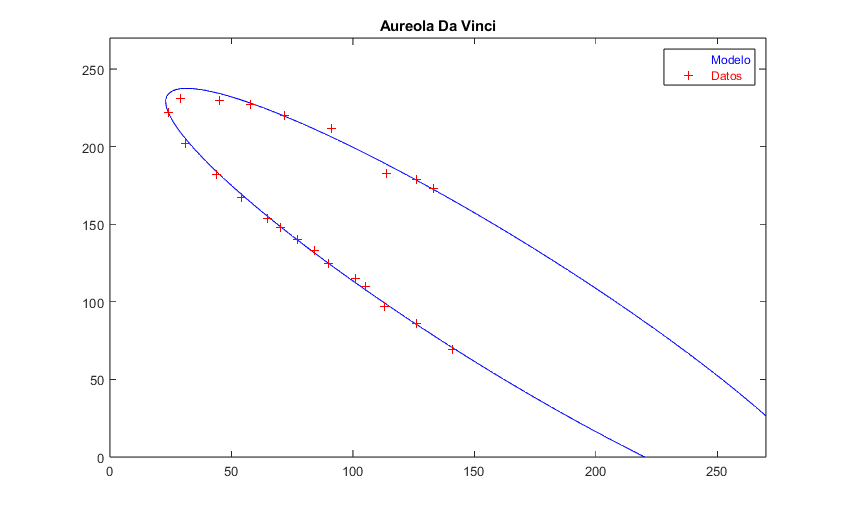

fleft = @(x,y) cleft(1)*x.^2+cleft(2)*y.^2+cleft(3)*x.*y+cleft(4)*x+cleft(5)*y-10000;
fimplicit(fleft,[0 270],'b-')
hold on
plot(x1,y1,'r+')
title('Aureola Da Vinci')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')
hold off

Ahora, para realizar el cálculo del error hallamos la norma del vector $ \mathbf{10000}- E_{left}\cdot c_{left}$

norm(10000*ones(22,1)-Eleft*cleft,2) %Norma matricial euclidiana

ans = 135.5643

Una vez hecho el proceso con la aureola izquierda, se repiten los mismos pasos con la aureola derecha. Se seleccionan manualmente 22 puntos del borde de la figura geométrica con ayuda del  siguiente código.

imshow('angeles.jpg')
[x2,y2] = ginput(22);

Se plantea el mismo modelo y se construye la matriz adecuada.

Eright = [x2.*x2 y2.*y2 x2.*y2 x2 y2];

El sistema de mínimos cuadrados es aplicado de la misma manera que en el caso anterior.

cright = mldivide(Eright'*Eright,10000*Eright'*ones(22,1));

Una vez terminado el cálculo, se obtiene:

fprintf('%g ',cright)

-0.0377761 -0.120876 -0.00209688 36.979 32.7035 

en donde $c_{right}=(A,B,C,D,E)^{T}$.

Para hacer una primera comparación, se realiza la gráfica de datos versus el modelo obtenido.

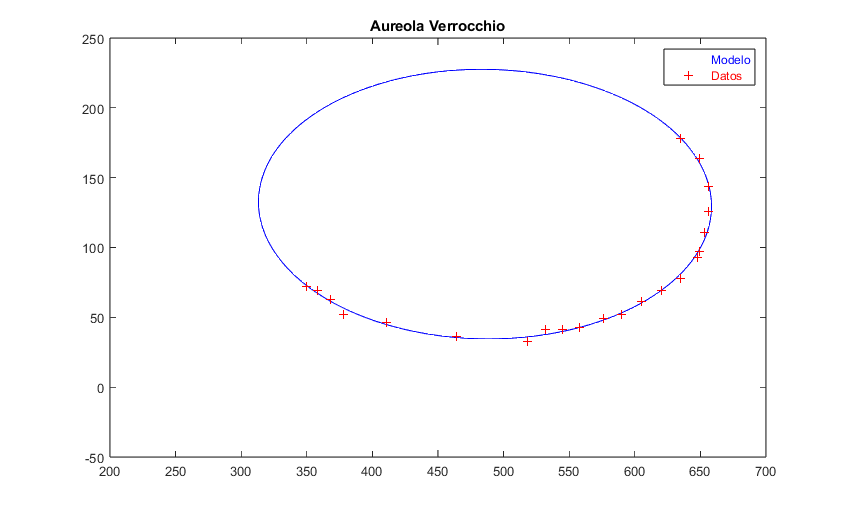

fright = @(x,y) cright(1)*x.^2+cright(2)*y.^2+cright(3)*x.*y+ cright(4)*x+cright(5)*y-10000;
fimplicit(fright,[200 700 -50 250],'b-')
hold on
plot(x2,y2,'r+')
title('Aureola Verrocchio')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')
hold off

Finalmente, se obtiene el error entre el modelo y los datos calculados.

norm(10000*ones(22,1)-Eright*cright,2) %Norma matricial euclidiana

ans = 162.4781

En conclusión, la aureola izquierda se ajusta mejor a una elipse que la aureola derecha (revise el código a continuación), esto quiere decir en términos prácticos que Leonardo Da Vinci superó a su maestro Andrea del Verrochio (considerando el modelo propuesto de la elipse, el método de mínimos cuadrados y la toma de datos como adecuados para la solución del problema).

% ¿Da Vinci superó a Verrochio?
% Si (1)
% No (0)
norm(10000*ones(22,1)-Eleft*cleft,2)<norm(10000*ones(22,1)-Eright*cright,2)

ans = logical
   1
